clc; close all; clear variables
set(groot, 'defaultAxesTickLabelInterpreter','latex'); set(groot, 'defaultLegendInterpreter','latex');set(groot,'defaulttextinterpreter','latex');  

## **DYNAMICS AND CONTROL OF VEHICLES AND ROBOTS**

## Example: Rolling radius estimation

**University of Trento**

*A.Y. 2019/2020*

F. Biral

E. Pagot

## Intro

In this script the telemetry data from the P1 experimental vehicles are loaded. This Matlab Live Script can be used as the structure for your project script. 

Click "Save as..." and save this script as .m in order to obtain a classic Matlab script.

## Load Vehicle Parameters

The script loads the vehicle main parameters in the `vehicle` struct. See the script `p1_parameters.m` for comments about parameters names and units.

p1_parameters

## Load Datasets

The following test are available.

**DATASET NAME DESCRIPTION**

RAMP_STEER_L Left-hand ramp steer 10 m/s

RAMP_STEER_R Right-hand ramp steer 10 m/s

SINE_STEER_IS Sine wave steering at increasing speeds

SP_100FT_CR_IS_CCW Steering pad 100 ft circle constant radius increasing speed counter-clockwise

SP_100FT_CR_IS_CW Steering pad 100 ft circle constant radius increasing speed clockwise

STRAIGHT_LINE_0 Straight line at constant speed

STRAIGHT_LINE_1 Straight line in one direction

STRAIGHT_LINE_2 Straight line in the opposite direction

STEP_STEER Step steer

load("Dataset/STRAIGHT_LINE_0.mat");

The loaded variable is a struct cointaing the following telemetry signals:

% DATA			UNITS		DESCRIPTION
% time                  s               acquisition time
% yaw			rad		yaw angle
% yaw_rate		rad/s 		yaw rate at COM
% roll			rad		roll at COM
% roll_rate		rad/s 		roll rate at COM
% long_vel		m/s 		longitudinal velocity of the COM
% lat_vel		m/s 		lateral velocity of the COM
% axG			m/s^2		longitudinal acceleration of the COM
% ayG			m/s^2 		lateral acceleration of the COM
% body_slip		rad		vehicle side slip angle (at COM)
% omega_FL		rad/s 		wheel angular speed
% omega_FR		rad/s 		wheel angular speed
% omega_RL		rad/s 		wheel angular speed
% omega_RR		rad/s 		wheel angular speed
% front_slip_angle      rad		equivalent (single track) slip angle at front axle
% rear_slip_angle       rad		equivalent (single track) slip angle at rear axle
% Fx_FL			N		tyre longitudinal force
% Fy_FL			N		tyre lateral force
% Fz_FL			N		tyre vertical force
% Fx_FR			N		tyre longitudinal force
% Fy_FR			N		tyre lateral force
% Fz_FR			N		tyre vertical force
% x_pos			m		COM position x coordinate (from GPS)
% y_pos			m		COM position y coordinate (from GPS)
% z_pos			m		COM position z coordinate or altitude (from GPS)
% delta_L		rad		steering angle of the front left wheel
% delta_R		rad		steering angle of the front right wheel
% delta_HW 		rad		handwheel steering angle

## Estimate the wheel rolling radius

Estimate the rolling radius from constant speed straight driving. We use the front wheels velocities because the front wheels are in free rolling conditions (we neglect the slip generated by the rolling resistance).

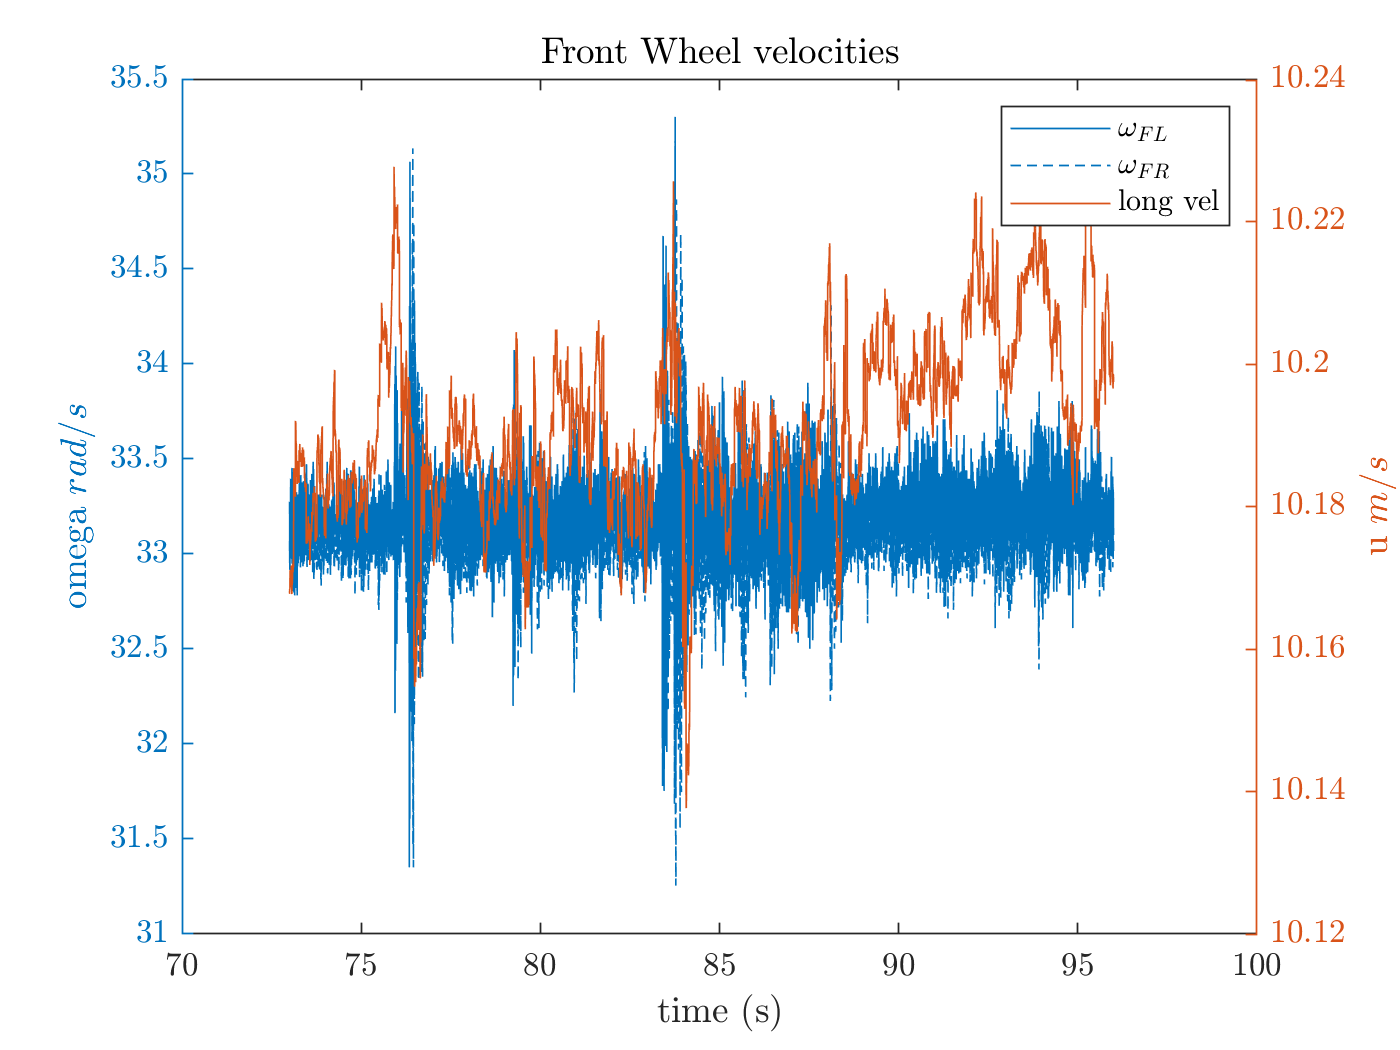

figure
yyaxis left
plot(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.omega_FL,'DisplayName','$\omega_{FL}$')
hold on
plot(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.omega_FR,'DisplayName','$\omega_{FR}$')
xlabel('time (s)');ylabel('omega $rad/s$');
title('Front Wheel velocities');

yyaxis right
plot(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.long_vel,'DisplayName','long vel')
xlabel('time (s)');ylabel('u $m/s$');
legend

The kinematic relationship between the longitudinal velocity and the wheel angular speed is the following: $u = \omega_{wheel}*R$

ft = fittype('R.*x'); 
fit_R = fit(mean([STRAIGHT_LINE_0.omega_FL,STRAIGHT_LINE_0.omega_FR],2),STRAIGHT_LINE_0.long_vel,ft,'StartPoint', vehicle.R);

fprintf(' The estimated rolling radius is: %6.3f\n', fit_R)

 The estimated rolling radius is:  0.307


fprintf(' The wheel radius given is: %6.3f\n', vehicle.R)

 The wheel radius given is:  0.308
